# **HW10**

## **1st Attempt: **8.00/14.00

# Q1

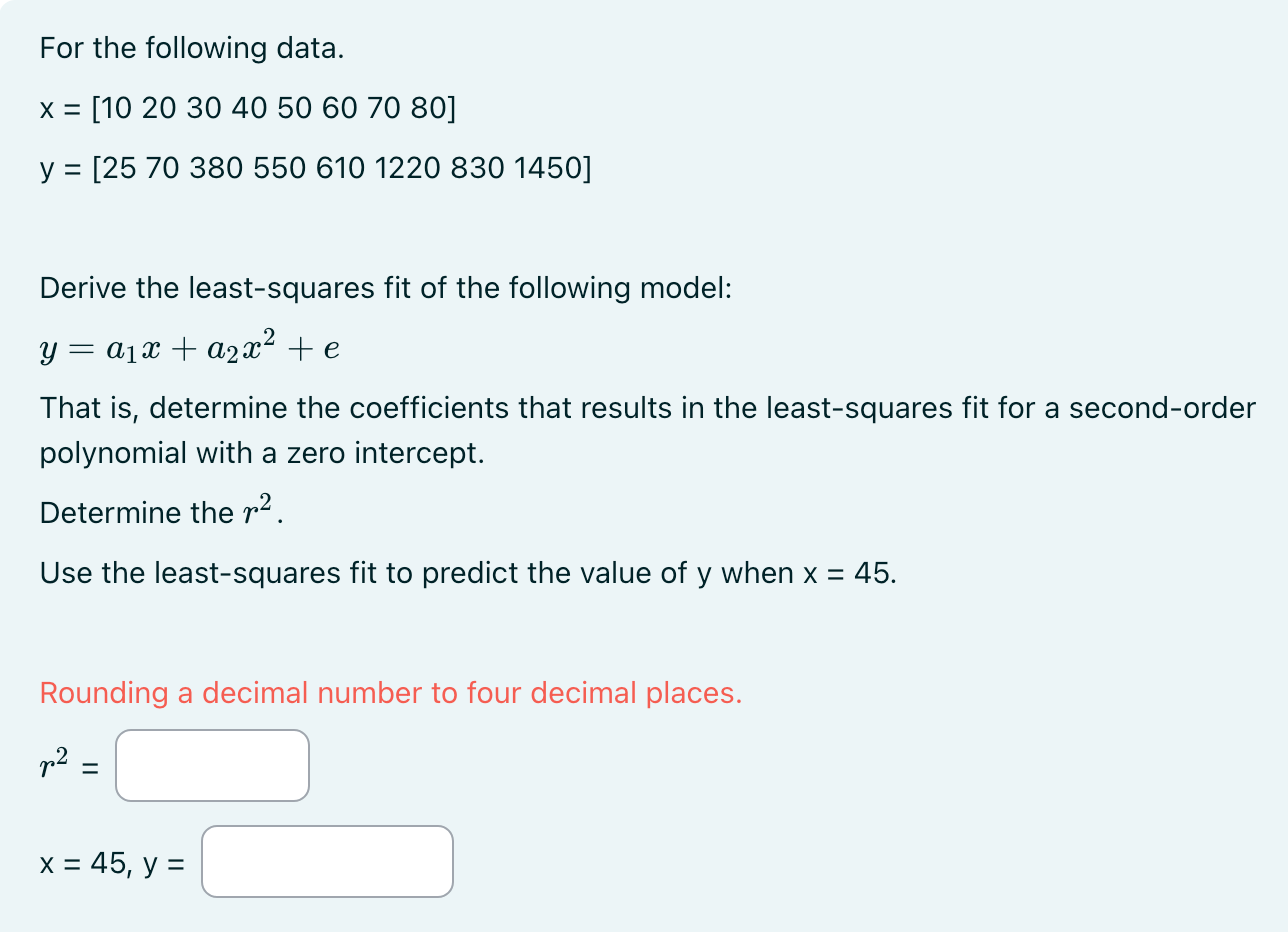

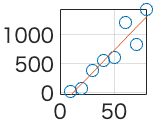

a =    19.4702 -234.2857


r2 = 0.8805

xtest = 45

関数または変数 'p2' が認識されません。

x = [10 20 30 40 50 60 70 80];
y = [25 70 380 550 610 1220 830 1450];


# Q2

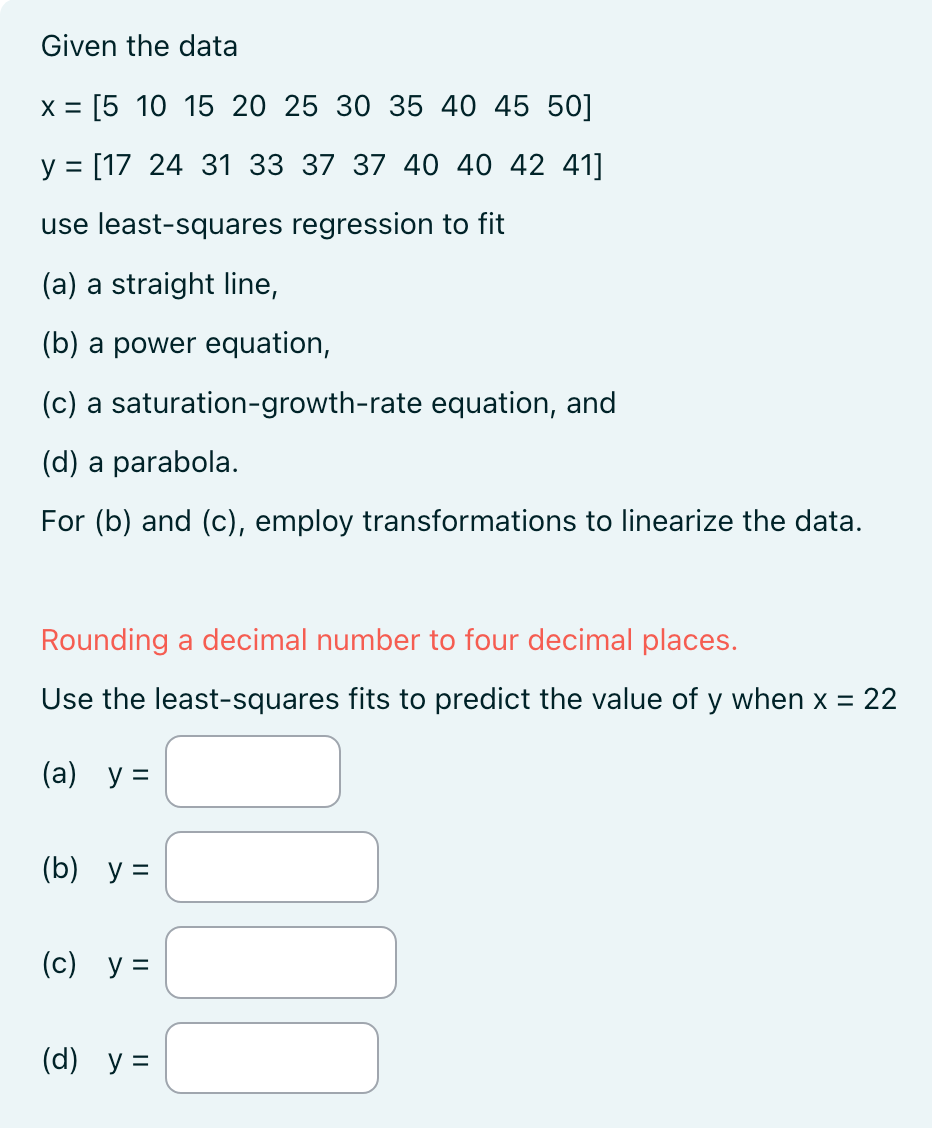

% dataset
x = [5  10  15  20  25  30  35  40  45  50];
y = [17  24  31  33  37  37  40  40  42  41];
xplot = linspace(min(x), max(x), 100)
xtest = 22

% Linear (straight line) fit
Lp1 = polyfit(x, y, 1)
Lyy1 = polyval(Lp1, x)
Lytest1 = polyval(Lp1, xtest)

% Power equation linearization [can't use polyfit/polyval; no degrees]
Pnew_x = log10(x)
Pnew_y = log10(y)
[Pa, ~] = linregr(Pnew_x, Pnew_y)
Pslp = Pa(1)
Pint = Pa(2)
Palpha = 10^Pint
Pbeta = Pslp
Pytest = Palpha .* (xtest .^ Pbeta)
% Pyplot = Palpha .* (xplot .^ Pbeta)
% plot(x, y, 'o', xplot, Pyplot)

% Saturation growth rate linearization [can't use polyfit/polyval; no degrees]
Snew_x = 1 ./ x
Snew_y = 1 ./ y
[Sa, ~] = linregr(Snew_x, Snew_y)
Sslp = Sa(1)
Sint = Sa(2)
Salpha = 1 / Sint
Sbeta = Salpha * Sslp
% Syplot = Salpha .* (xplot ./ (Sbeta + xplot))
Sytest = Salpha .* (xtest ./ (Sbeta + xtest))
% plot(x, y, 'o', xplot, Syplot, '-')

% parabola (Quadratic) fit
Qp2 = polyfit(x, y, 2)
Qyy2 = polyval(Qp2, x)
Qytest2 = polyval(Qp2, xtest)

# Q3

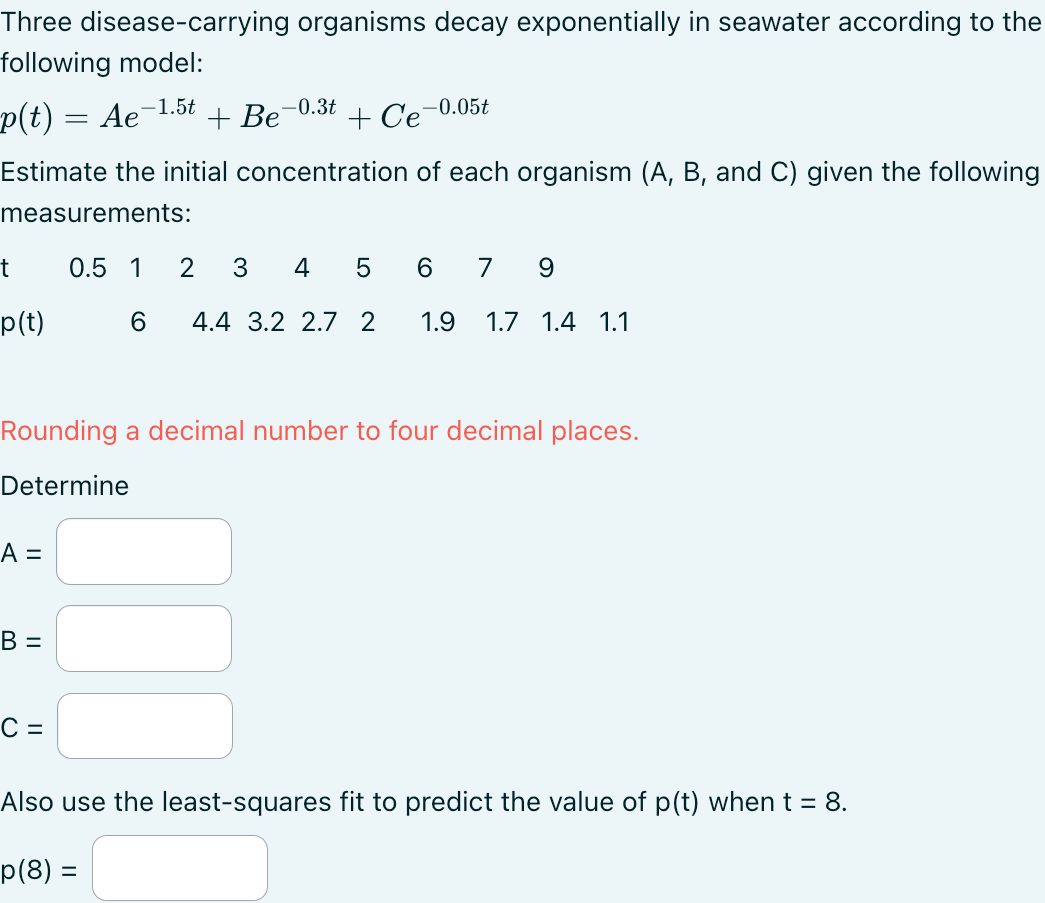

t 	= [0.5   1     2     3      4      5      6      7      9];
p 	= [6      4.4  3.2  2.7   2      1.9    1.7   1.4   1.1];
ttest = 8
p = polyfit(t, p, 2)
p(1)
p(2)
p(3)
functest = p(1)*exp(-1.5.*ttest) + p(2)*exp(-0.3.*ttest) + p(3)*exp(-0.05.*ttest)

# Q4

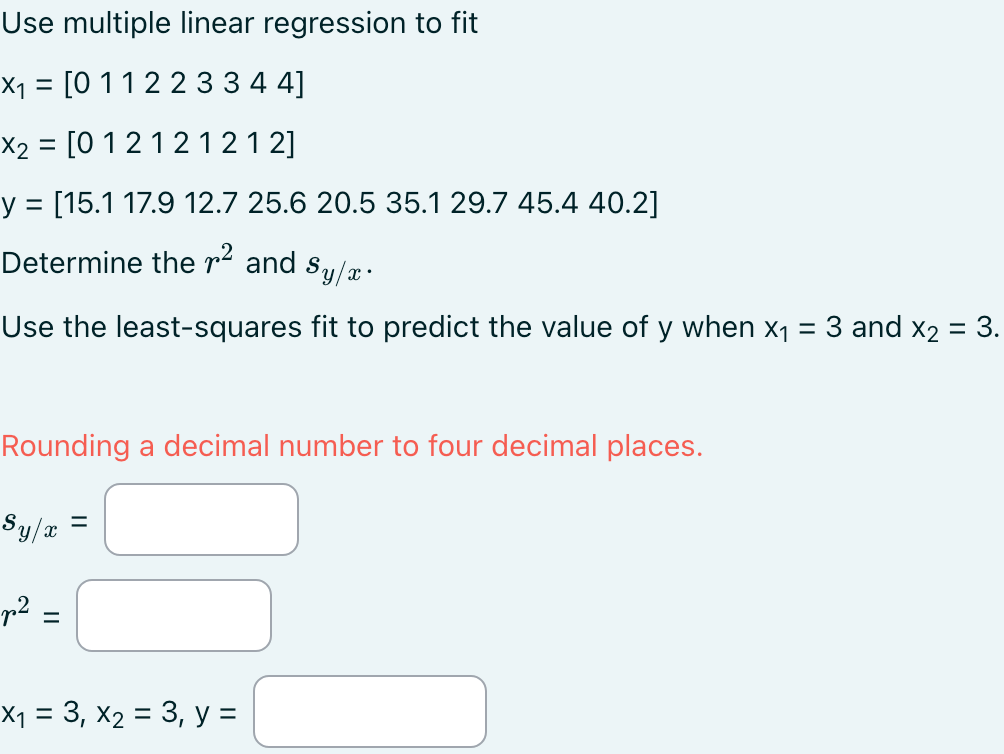

x1 = [0 1 1 2 2 3 3 4 4]';
x2 = [0 1 2 1 2 1 2 1 2]';
y = [15.1 17.9 12.7 25.6 20.5 35.1 29.7 45.4 40.2]';
Z = [ones(size(y)), x1, x2]
a = (Z' * Z) \ (Z' * y)
sr = sum((y - (Z*a)).^2)
st = sum((y - mean(y)).^2)
r2 = 1 - (sr/st)
syx = sqrt(sr/(length(y)-3))
ypred = a(1) + (a(2) * 3) + (a(3) * 3)

# Q5

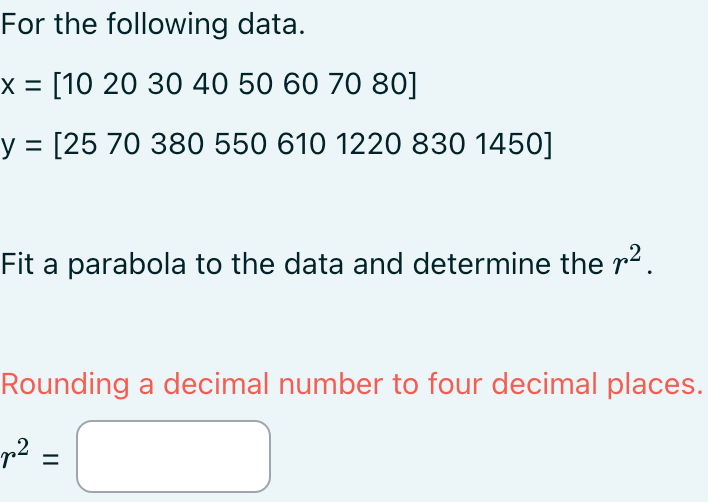

x = [10 20 30 40 50 60 70 80];
y = [25 70 380 550 610 1220 830 1450];
p = polyfit(x, y, 2)
sr = sum((y - polyval(p, x)) .^ 2)
st = sum((y - mean(y)) .^2)
r2 = 1 - (sr/st)

### `linregr` function

function [a, r2] = linregr(x,y)
    % linregr: linear regression curve fitting
    % [a, r2] = linregr(x,y): Least squares fit of straight
    % line to data by solving the normal equations
    % input:
    % x = independent variable
    % y = dependent variable
    % output:
    % a = vector of slope, a(1), and intercept, a(2)
    % r2 = coefficient of determination
    n = length(x);
    if length(y)~=n, error('x and y must be same length'); end
    x = x(:); y = y(:); % convert to column vectors
    sx = sum(x); sy = sum(y);
    sx2 = sum(x.*x); sxy = sum(x.*y); sy2 = sum(y.*y);
    a(1) = (n*sxy-sx*sy)/(n*sx2-sx^2);
    a(2) = sy/n-a(1)*sx/n;
    r2 = ((n*sxy-sx*sy)/sqrt(n*sx2-sx^2)/sqrt(n*sy2-sy^2))^2;
    % create plot of data and best fit line
    xp = linspace(min(x),max(x),2);
    yp = a(1)*xp+a(2);
    plot(x,y,'o',xp,yp)
    grid on
end